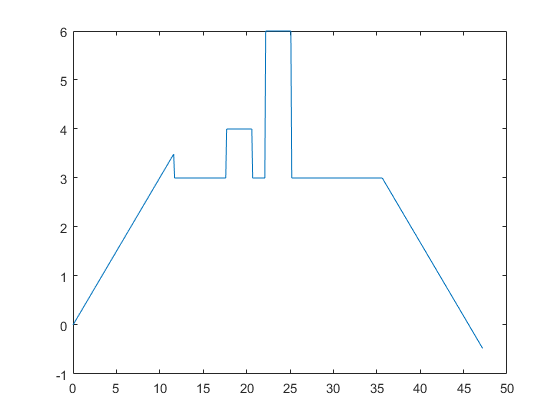

i = 1;
terrain = zeros((47.2/.1),1);
step = zeros((47.2/.1),1);
for r = 0:.1:47.25
    terrain(i)= RoughTerrain(r);
    step(i) = r;
    i = i+1;
end 
plot(step,terrain)

ME4322 = TankTread;
ME4322.addMotor(1000,25,7,32,3,9,2,20,1);
ME4322.A_motor;
ME4322.B_motor;
ME4322.TankBuilder(1,1,1,1,1,1,1,1)
ME4322.A_tank

ans =          0    1.0000         0         0         0         0
         0         0         0    1.0000         0         0
         0         0         0   -1.0000         0         0
         0    1.0000    6.0000         0         0    0.8571
         0         0         0         0         0   -0.8571
         0         0         0    1.0000   -1.0000         0


ME4322.B_tank

ans =      1
     1
     0
     0
     0
     0


ME4322.Driving(terrain);

Unable to perform assignment because the size of the left side is 1-by-6 and the size of the right side is 6-by-6.

Error in TankTread/Driving (line 38)
             obj.output(i,1:6) = obj.A_tank*x + obj.B_tank*z_values(i,1);

ME4322.output
%x = [0;0;0;0;0;0]
%ME4322.A_tank*x + ME4322.B_tank*terrain(10,1)
